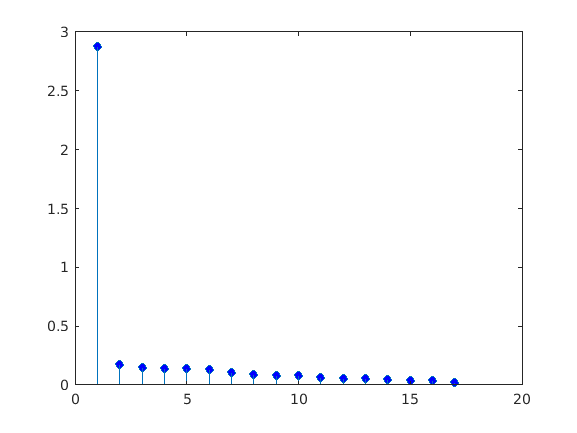

load('ircoeffs.mat')

%% Identification
% Hankel matrix and its SVD
Hir = hankel(irvec(2:18), irvec(18:end));
[Uh,Sh,Vh] = svd(Hir,'econ');
% Plot the resulting singular values to guess the order
figure;
stem((1:17), diag(Sh), 'markerfacecolor', 'b')


% Estimate obsrv and ctrb matrices
nx = 1;
Obnhat = Uh(:,1:nx) * sqrt(Sh(1:nx,1:nx));
Cbnhat = sqrt(Sh(1:nx,1:nx)) * Vh(:,1:nx)';

% Estimate SS matrices
Dhat = 0.0108;  % g[k=0]
Chat = Obnhat(1,:);
Bhat = Cbnhat(:,1);
Ahat = pinv(Obnhat(1:end-1,:)) * Obnhat(2:end,:);

% Reconstruct the TF
Ghat_ss = ss(Ahat,Bhat,Chat,Dhat,1)

Ghat_ss =
 
  A = 
           x1
   x1  0.8096
 
  B = 
            u1
   x1  -0.9952
 
  C = 
            x1
   y1  -0.9956
 
  D = 
           u1
   y1  0.0108
 
Sample time: 1 seconds
Discrete-time state-space model.



Ghat_tf = tf(Ghat_ss)

Ghat_tf =
 
  0.0108 z + 0.982
  ----------------
     z - 0.8096
 
Sample time: 1 seconds
Discrete-time transfer function.




[num,den] = tfdata(Ghat_tf,'v');
